Straight Needle Drop

straight_needle_drop = figure

straight_needle_drop =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


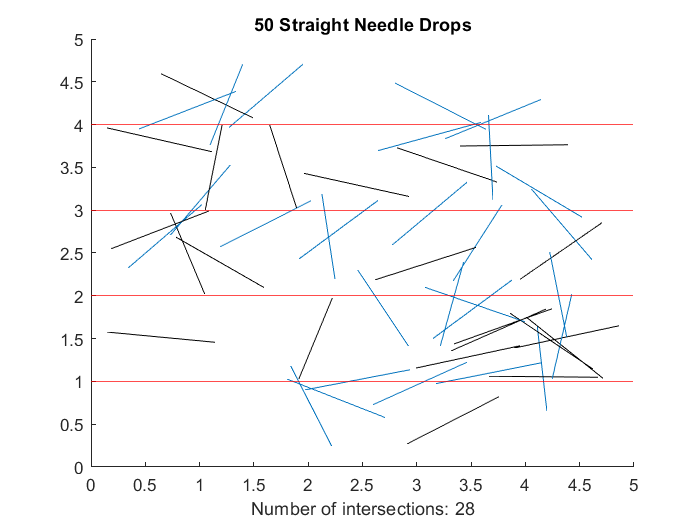

clear, clc

%needle information
straight_needle_length = 1;
number_of_straight_needle = 50;

% create grid
axis([0,5,0,5]);
h1 = yline(1, "r");
h2 = yline(2, "r");
h3 = yline(3, "r");
h4 = yline(4, "r");

%get the following information about each dropped needle
[midpoint, angle, intersect] = straight_needle_drop(straight_needle_length, number_of_straight_needle);

hold on
title({number_of_straight_needle + " Straight Needle Drops"})


straight_needle_intersections = 0;
%drop the needles, blue needle = intersected, black needle = didn't intersect
for i=1:number_of_straight_needle
    if (intersect(i, 1) == 1)
        plot([intersect(i,2), intersect(i, 4)], [intersect(i, 3), intersect(i, 5)], "Color", '#0072BD');
    else
         plot([intersect(i,2), intersect(i, 4)], [intersect(i, 3), intersect(i, 5)], "black");
    end
    straight_needle_intersections = straight_needle_intersections + intersect(i, 1);
    xlabel({"Number of intersections: " + straight_needle_intersections})
    drawnow %<-- REMOVE THIS IF IT IS TAKES TOO LONG TO LOAD
end

Bent Needle Drop (constant angle)

bent_needle_constant__angle_drop = figure

bent_needle_constant__angle_drop =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


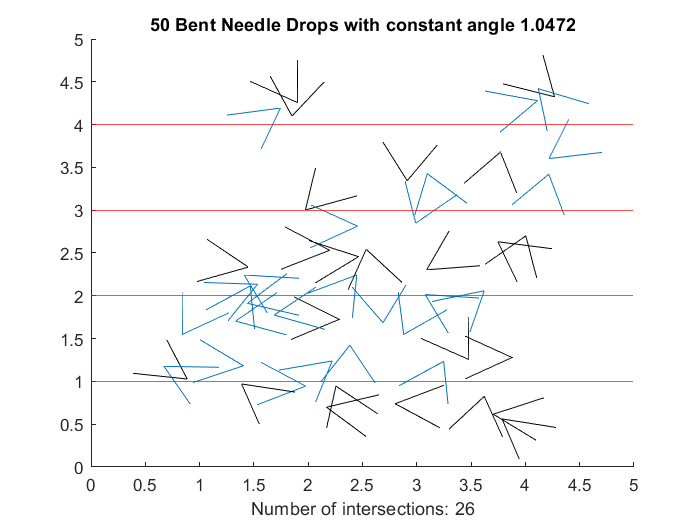

clear, clc
%length of entire needle, not one side of the needle
bent_needle_length = 1;
number_of_bent_needles = 50;
%angle between needle legs, select 0 for random bend
bend = pi/3;

% create grid
axis([0,5,0,5]);
h1 = yline(1, "r");
h2 = yline(2, "r");
h3 = yline(3, "r");
h4 = yline(4, "r");

%Bent needle drop with constant angle
[bent_intersect] = bent_needle_drop(bent_needle_length, bend, number_of_bent_needles);

hold on
title({number_of_bent_needles + " Bent Needle Drops with constant angle " + bend})

bent_intersections = 0;
%drop the bent needles, blue = intersected needle, black = didn't intersect
for i=1:number_of_bent_needles
    if (bent_intersect(i, 1) == 1)
        plot([bent_intersect(i, 2), bent_intersect(i, 4)], [bent_intersect(i, 3), bent_intersect(i, 5)], "Color", '#0072BD');
        plot([bent_intersect(i, 4), bent_intersect(i, 6)], [bent_intersect(i, 5), bent_intersect(i, 7)], "Color", '#0072BD');
    else
        plot([bent_intersect(i, 2), bent_intersect(i, 4)], [bent_intersect(i, 3), bent_intersect(i, 5)], "black");
        plot([bent_intersect(i, 4), bent_intersect(i, 6)], [bent_intersect(i, 5), bent_intersect(i, 7)], "black");
    end
    bent_intersections = bent_intersections + bent_intersect(i, 1);
    xlabel({"Number of intersections: " + bent_intersections});
    drawnow %<-- REMOVE THIS IF IT IS TAKES TOO LONG TO LOAD
end

Bent Needle Drop (random angle)

bent_needle_random_angle_drop = figure

bent_needle_random_angle_drop =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


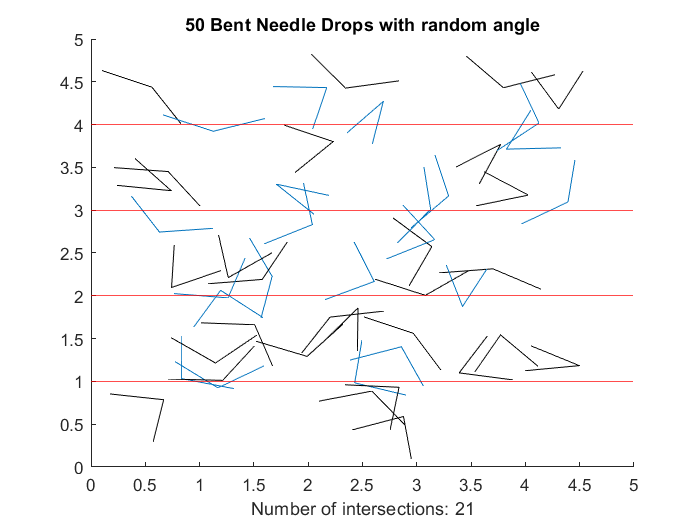

clear, clc
%length of entire needle, not one side of the needle
bent_needle_length = 1;
number_of_bent_needles = 50;
%angle between needle legs, select 0 for random bend
bend = 0;

% create grid
axis([0,5,0,5]);
h1 = yline(1, "r");
h2 = yline(2, "r");
h3 = yline(3, "r");
h4 = yline(4, "r");

%bent needle drop with random angle pi/6 to 5pi/6
[bent_intersect] = bent_needle_drop(bent_needle_length, bend, number_of_bent_needles);

hold on
title({number_of_bent_needles + " Bent Needle Drops with random angle"})

bent_intersections = 0;
%drop the bent needles, blue = intersected needle, black = didn't intersect
for i=1:number_of_bent_needles
    if (bent_intersect(i, 1) == 1)
        plot([bent_intersect(i, 2), bent_intersect(i, 4)], [bent_intersect(i, 3), bent_intersect(i, 5)], "Color", '#0072BD');
        plot([bent_intersect(i, 4), bent_intersect(i, 6)], [bent_intersect(i, 5), bent_intersect(i, 7)], "Color", '#0072BD');
    else
        plot([bent_intersect(i, 2), bent_intersect(i, 4)], [bent_intersect(i, 3), bent_intersect(i, 5)], "black");
        plot([bent_intersect(i, 4), bent_intersect(i, 6)], [bent_intersect(i, 5), bent_intersect(i, 7)], "black");
    end
    bent_intersections = bent_intersections + bent_intersect(i, 1);
    xlabel({"Number of intersections: " + bent_intersections});
    drawnow %<-- REMOVE THIS IF IT IS TAKES TOO LONG TO LOAD
end

Needle bent in 3 places (random bend)

threebent_needle_drop = figure

threebent_needle_drop =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


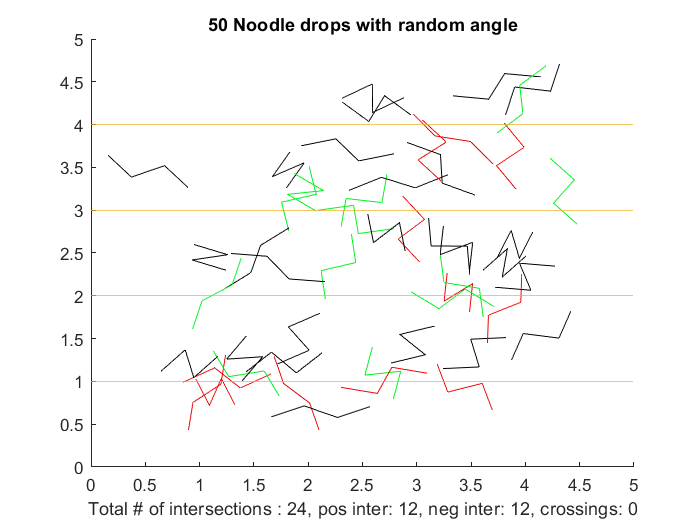


%length of the entire noodle
noodle_length = 1;
number_of_noodle_needles = 50;

% create grid
axis([0,5,0,5]);
h1 = yline(1, "Color", '#EDB120');
h2 = yline(2, "Color", '#EDB120');
h3 = yline(3, "Color", '#EDB120');
h4 = yline(4, "Color", '#EDB120');

[noodle_points, noodle_intersect] = drop_noodle(noodle_length, number_of_noodle_needles);

hold on
title({number_of_noodle_needles + " Noodle drops with random angle"})
    
noodle_inter = 0;
pos_inter = 0;
neg_inter = 0;

%drop the needles
for i=1:number_of_noodle_needles
    if (noodle_intersect(i, 1) == 1)
        %change color based on whether the noodle has a positive
        %interaction or negative interaction
        %blue if eye lands exactly on the horizontal line, green if positive intersection, red
        %if negative intersection, black if didn't intersect
        if (noodle_intersect(i, 2) > 0)
            plot([noodle_points(i, 1), noodle_points(i, 3)], [noodle_points(i, 2), noodle_points(i, 4)], "Color", '#00F220');
            plot([noodle_points(i, 3), noodle_points(i, 5)], [noodle_points(i, 4), noodle_points(i, 6)], "Color", '#00F220');
            plot([noodle_points(i, 5), noodle_points(i, 7)], [noodle_points(i, 6), noodle_points(i, 8)], "Color", '#00F220');
        elseif (noodle_intersect(i, 2) < 0)   
            plot([noodle_points(i, 1), noodle_points(i, 3)], [noodle_points(i, 2), noodle_points(i, 4)], "Color", '#EA0606');
            plot([noodle_points(i, 3), noodle_points(i, 5)], [noodle_points(i, 4), noodle_points(i, 6)], "Color", '#EA0606');
            plot([noodle_points(i, 5), noodle_points(i, 7)], [noodle_points(i, 6), noodle_points(i, 8)], "Color", '#EA0606');
        else
            plot([noodle_points(i, 1), noodle_points(i, 3)], [noodle_points(i, 2), noodle_points(i, 4)], "Color", '#0072BD');
            plot([noodle_points(i, 3), noodle_points(i, 5)], [noodle_points(i, 4), noodle_points(i, 6)], "Color", '#0072BD');
            plot([noodle_points(i, 5), noodle_points(i, 7)], [noodle_points(i, 6), noodle_points(i, 8)], "Color", '#0072BD');
        end
        
    else
        plot([noodle_points(i, 1), noodle_points(i, 3)], [noodle_points(i, 2), noodle_points(i, 4)], "black");
        plot([noodle_points(i, 3), noodle_points(i, 5)], [noodle_points(i, 4), noodle_points(i, 6)], "black");
        plot([noodle_points(i, 5), noodle_points(i, 7)], [noodle_points(i, 6), noodle_points(i, 8)], "black");
    end
    
    %count intersection, and positive and negative intersections
    noodle_inter = noodle_inter + noodle_intersect(i, 1);
    if (noodle_intersect(i, 2) > 0)
        pos_inter = pos_inter + noodle_intersect(i, 2);
    elseif (noodle_intersect(i, 2) < 0)
        neg_inter = neg_inter + noodle_intersect(i, 2)*-1;
    end
    crossings = neg_inter*-1 + pos_inter;
    
    xlabel({"Total # of intersections : " + noodle_inter + ", pos inter: " + pos_inter + ", neg inter: " + neg_inter + ", crossings: " + crossings });
    drawnow %<-- REMOVE THIS IF IT IS TAKES TOO LONG TO LOAD
end